# Task Data Inversion

The initial idea was to extract intrinsic connectivity from resting state data and then used these connectivity estimates when modeling task data.

So far we haven't had much success in capturing true directed connectivity parameters using sparse rDCM. 

But resting state data isn't the only place we can recover connectivity estimates from. In fact, the model with pruning is more extensively tested for task data. 

So in this notebook 

- we generate data with input (i.e. task data), 

- invert the model with pruning

- inspect connectivity and task parameter estimates

- generate data for a second task

- show how task involvement is overestimated without accounting for connectivity

- use recovered connectivity parameters from the first task to estimate the task parameters in the second task

## Long infrequent task to all nodes

stim_options = get_default_stim_options();
on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = 1/8;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [1,2,3];
stim_options.c = eye(stim_options.n);
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

Generate data for 20 "subjects" and invert it

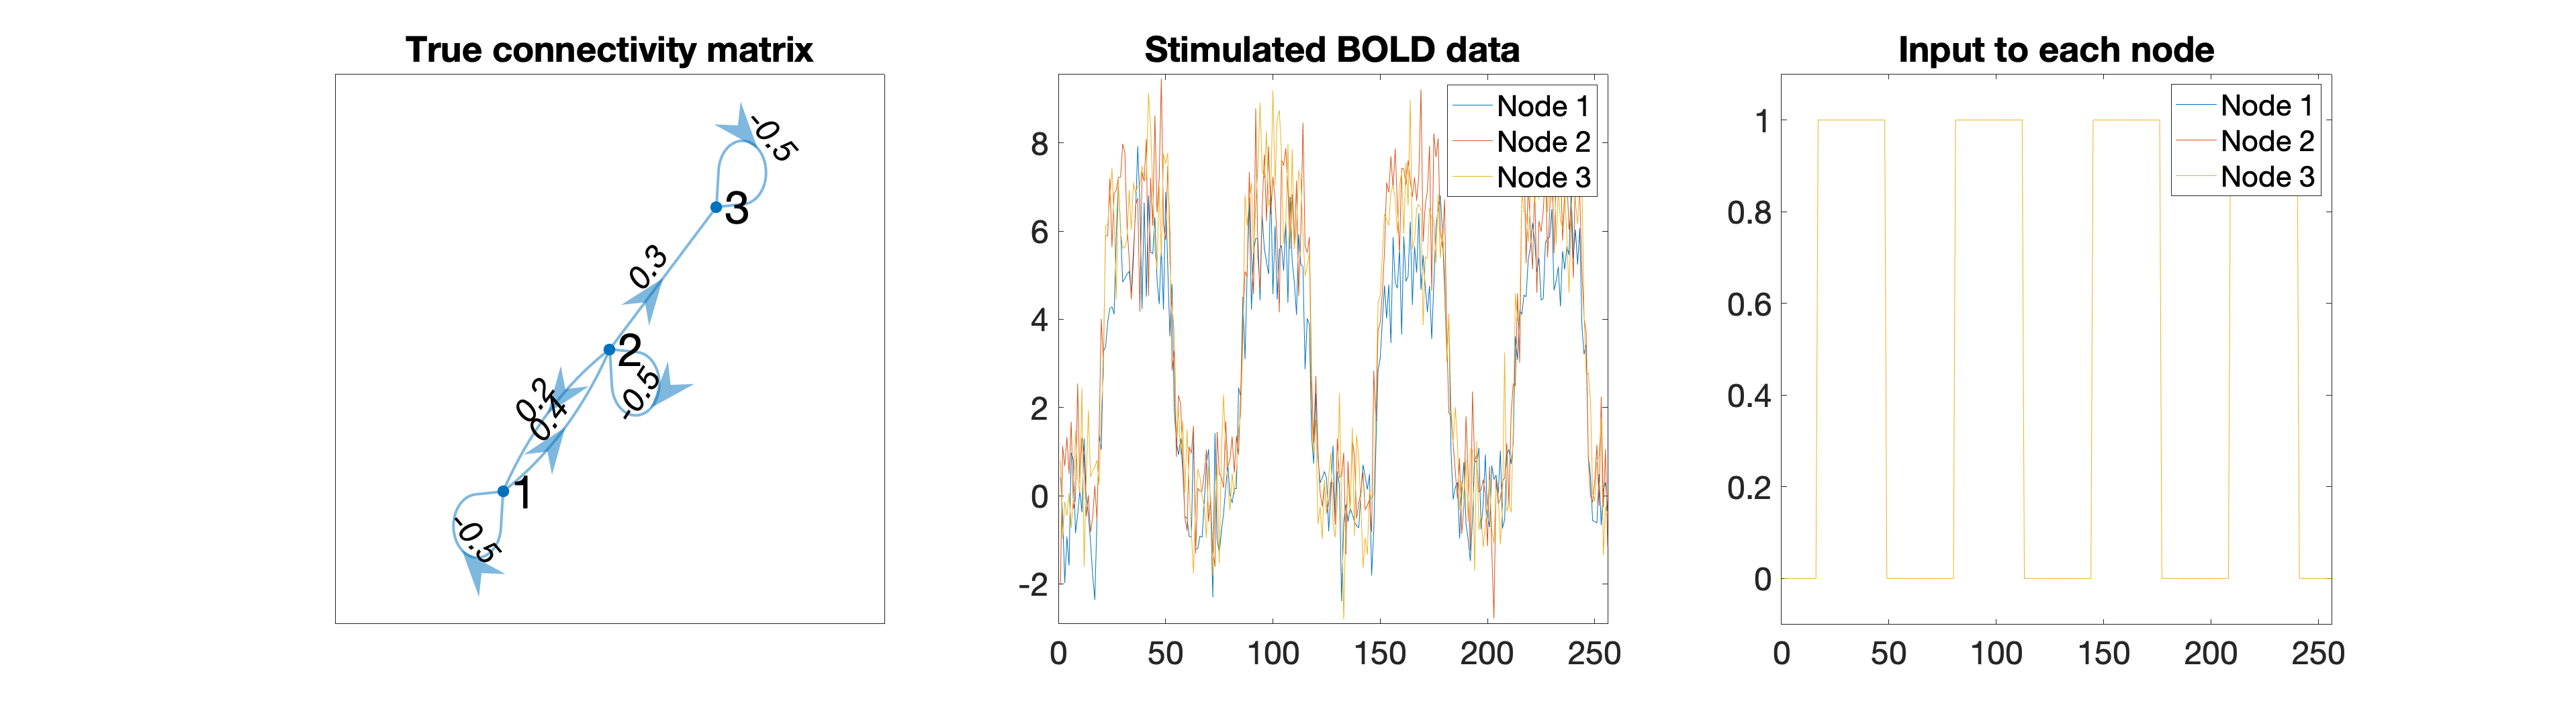


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


num_subj = 20;

for i=1:num_subj

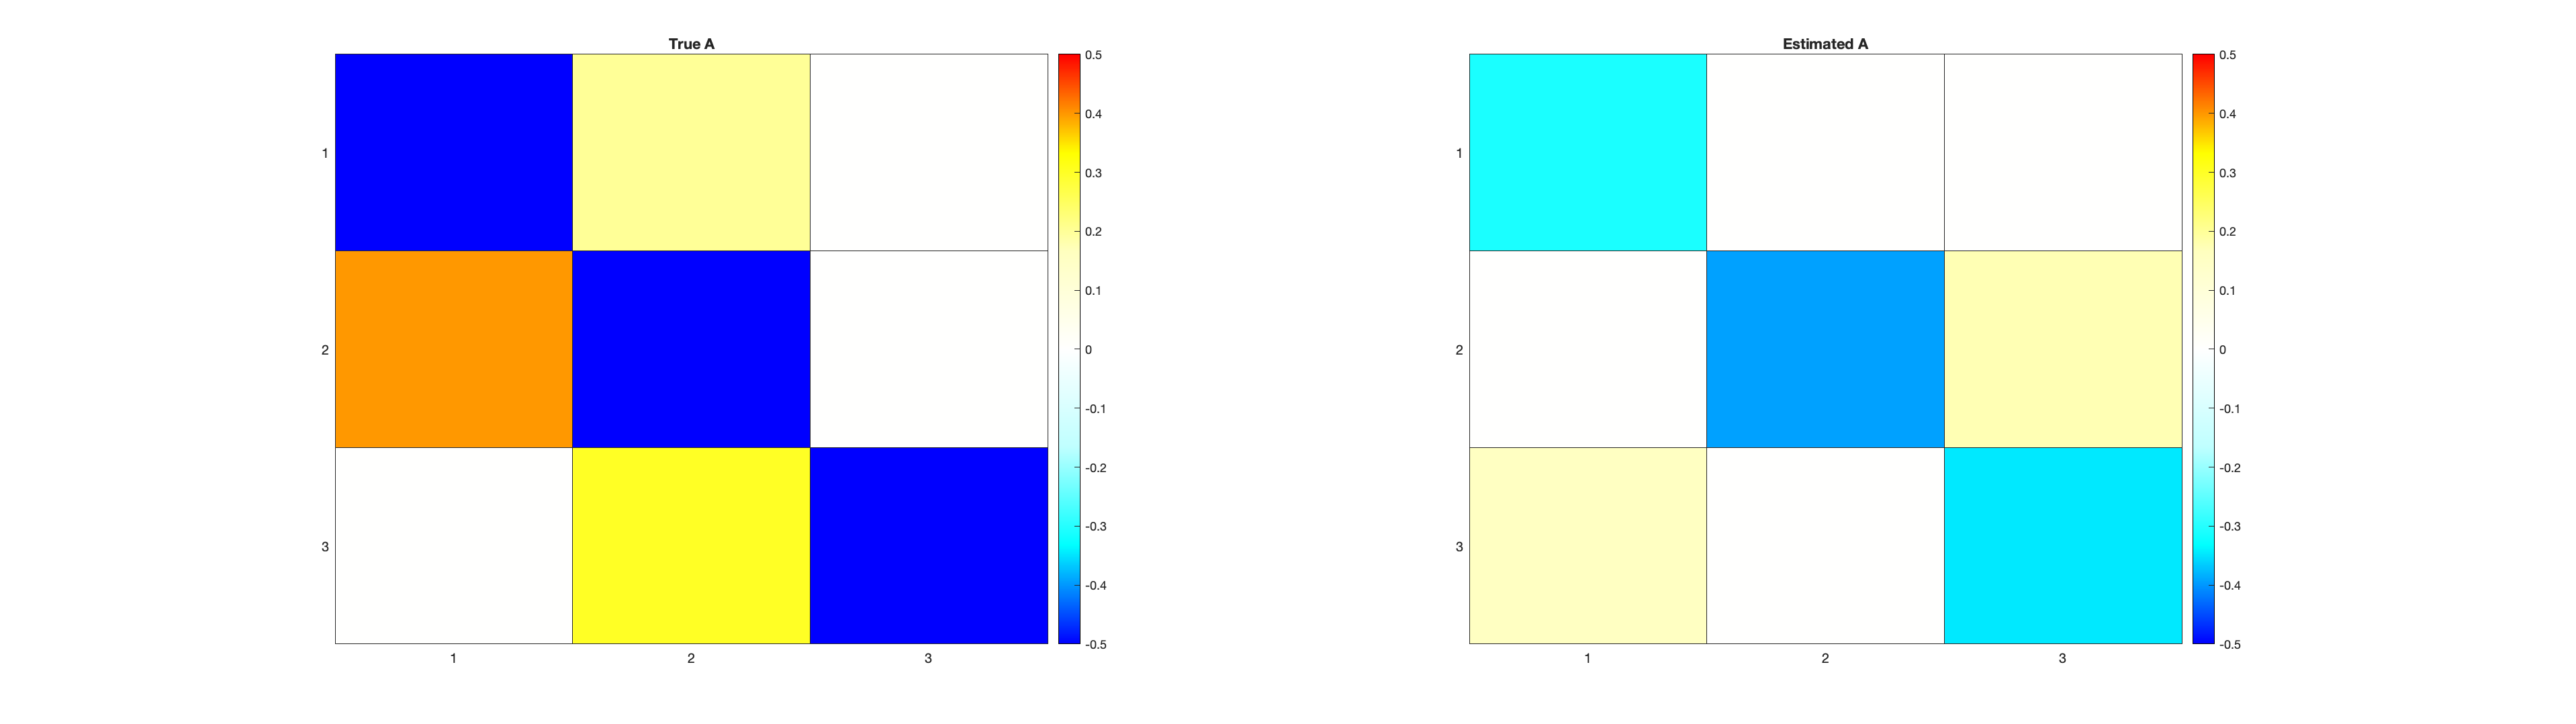

    [DCM, options] = make_task_fmri(stim_options);
    [output, options] = tapas_rdcm_estimate(DCM, 's', options, 2);

end



Plot one example subjects network, timeseries and input

plot_sim_data(DCM)

Plot result. True vs. average of 20 estimated matrices

plot_true_est_connectivity(DCM, output)

## Short but frequent task to all nodes

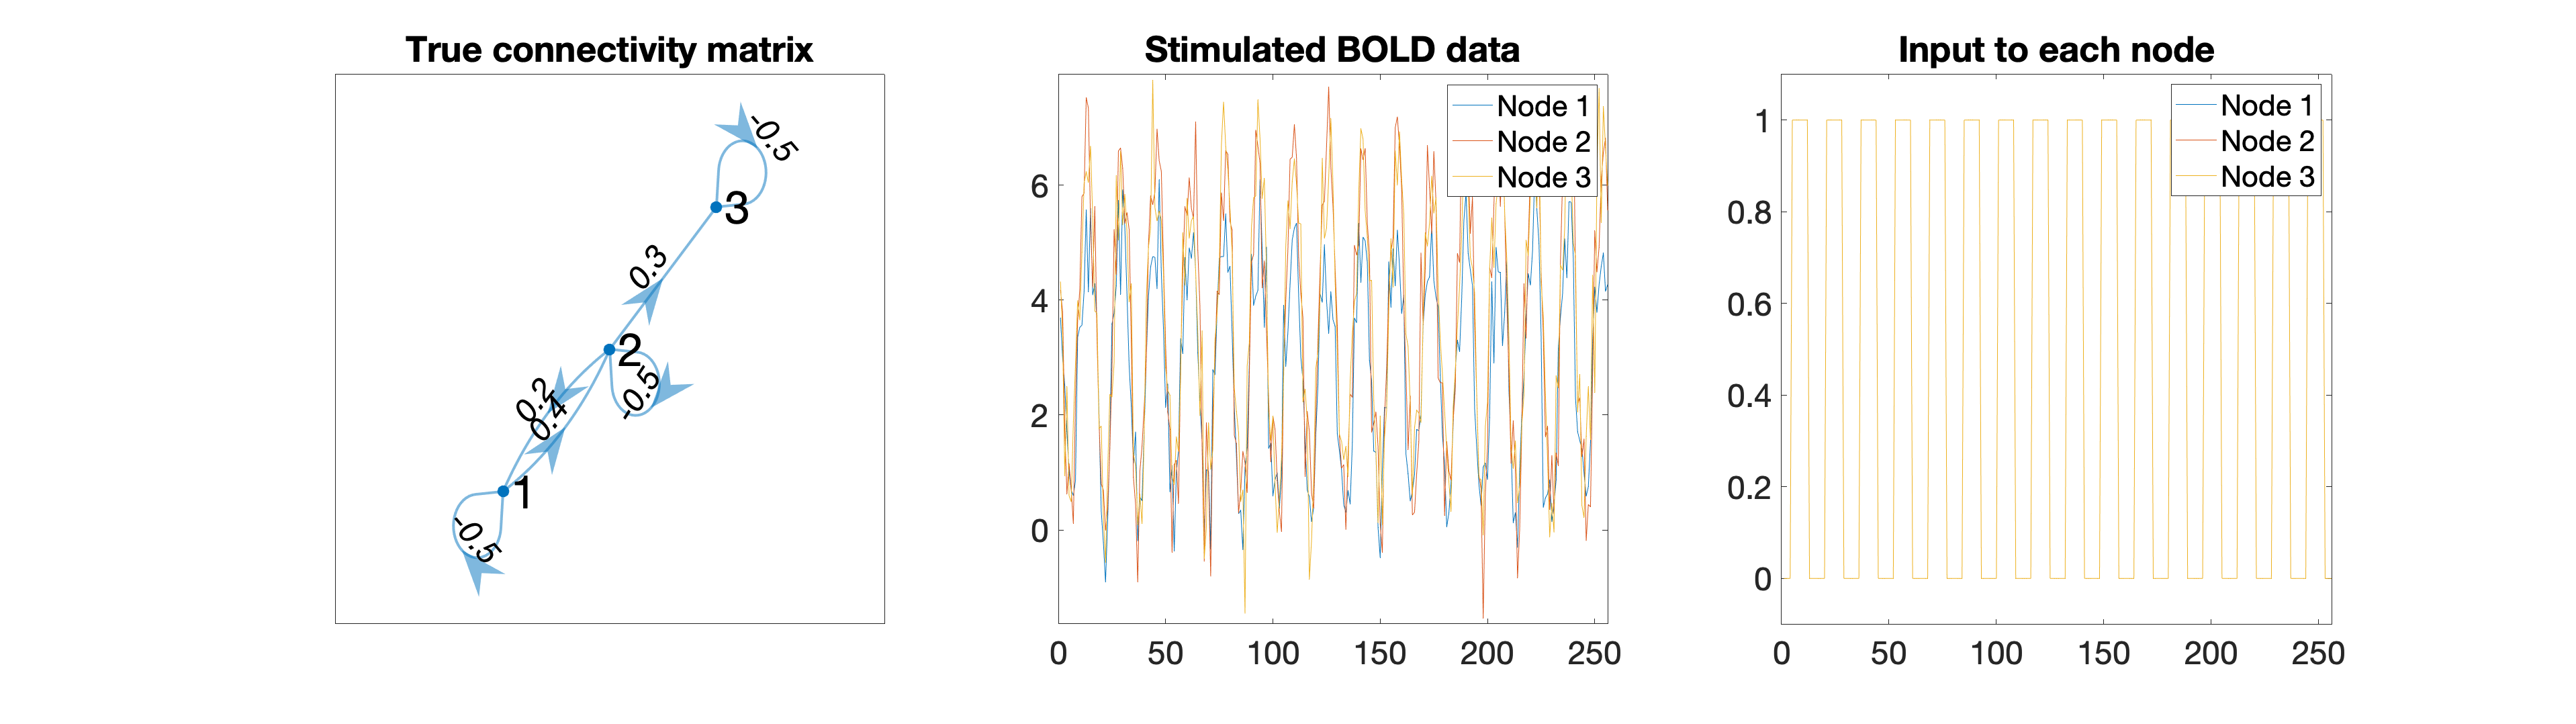


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


on_len = 16;
off_len = 8;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = [1,2,3];
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

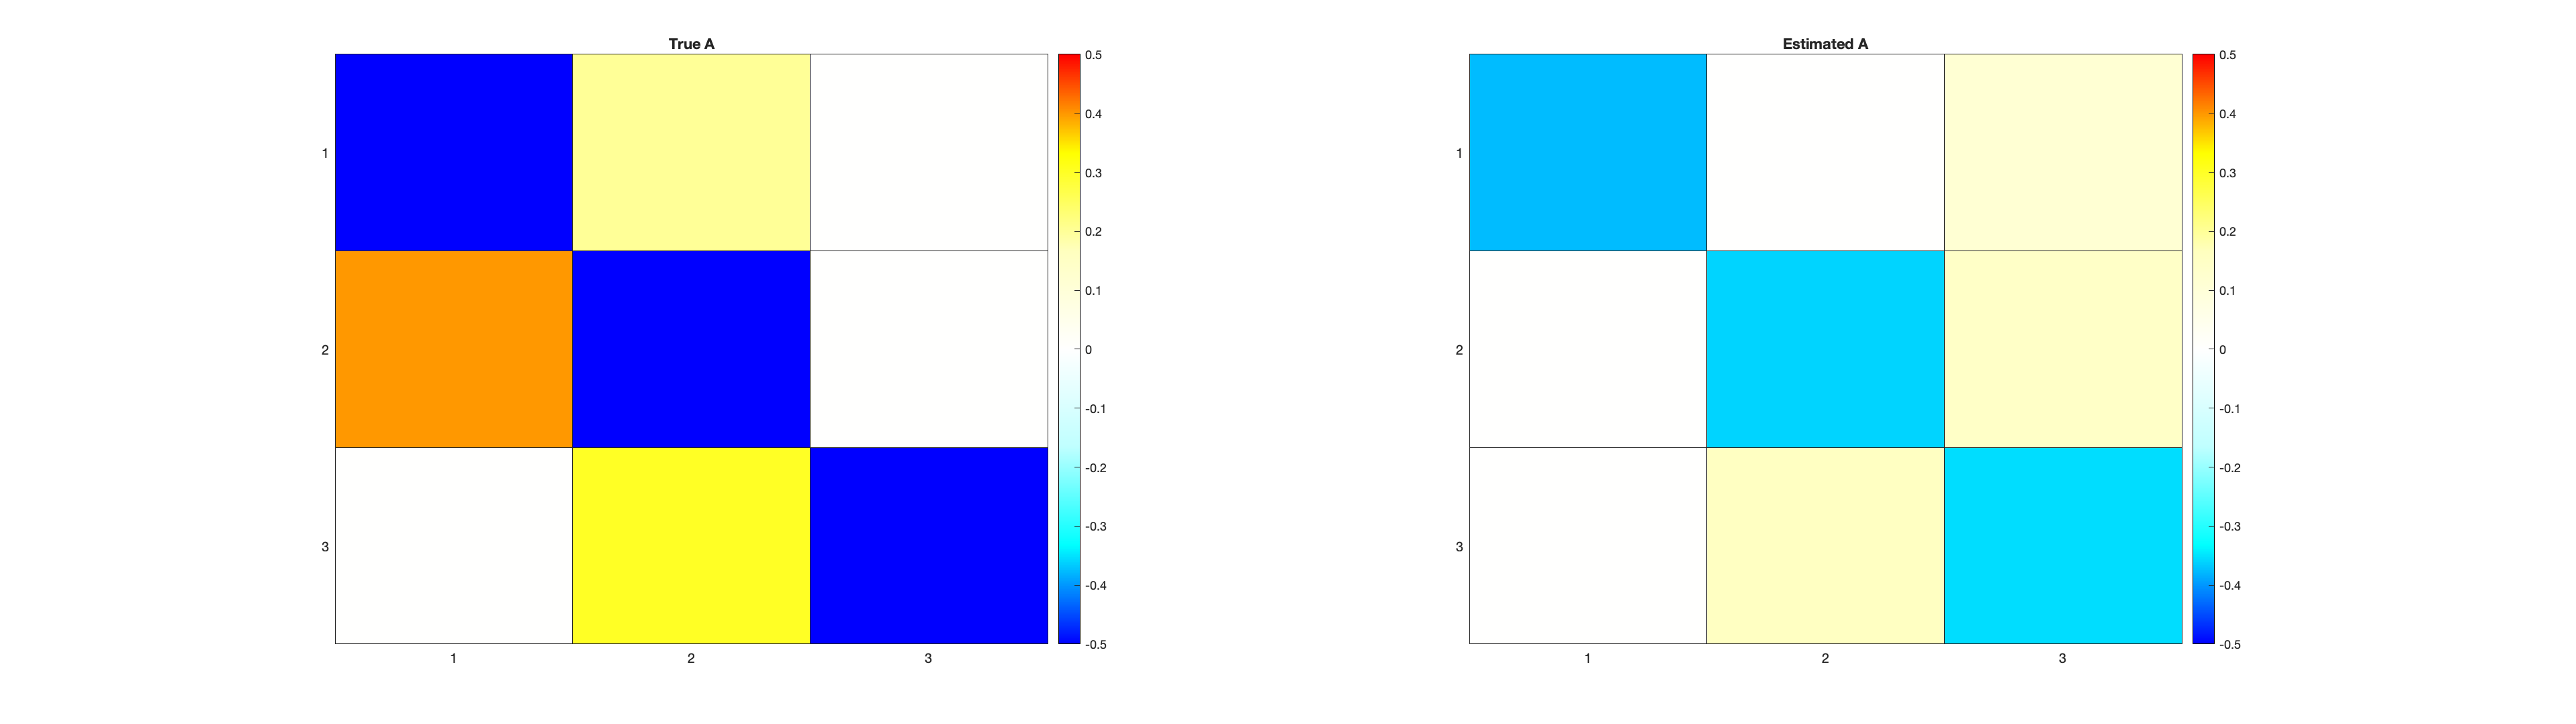

[DCM, options] = make_task_fmri(stim_options);

plot_sim_data(DCM)
[output, options] = tapas_rdcm_estimate(DCM, 's', options, 2);
plot_true_est_connectivity(DCM, output)

## Short but frequent task to one node

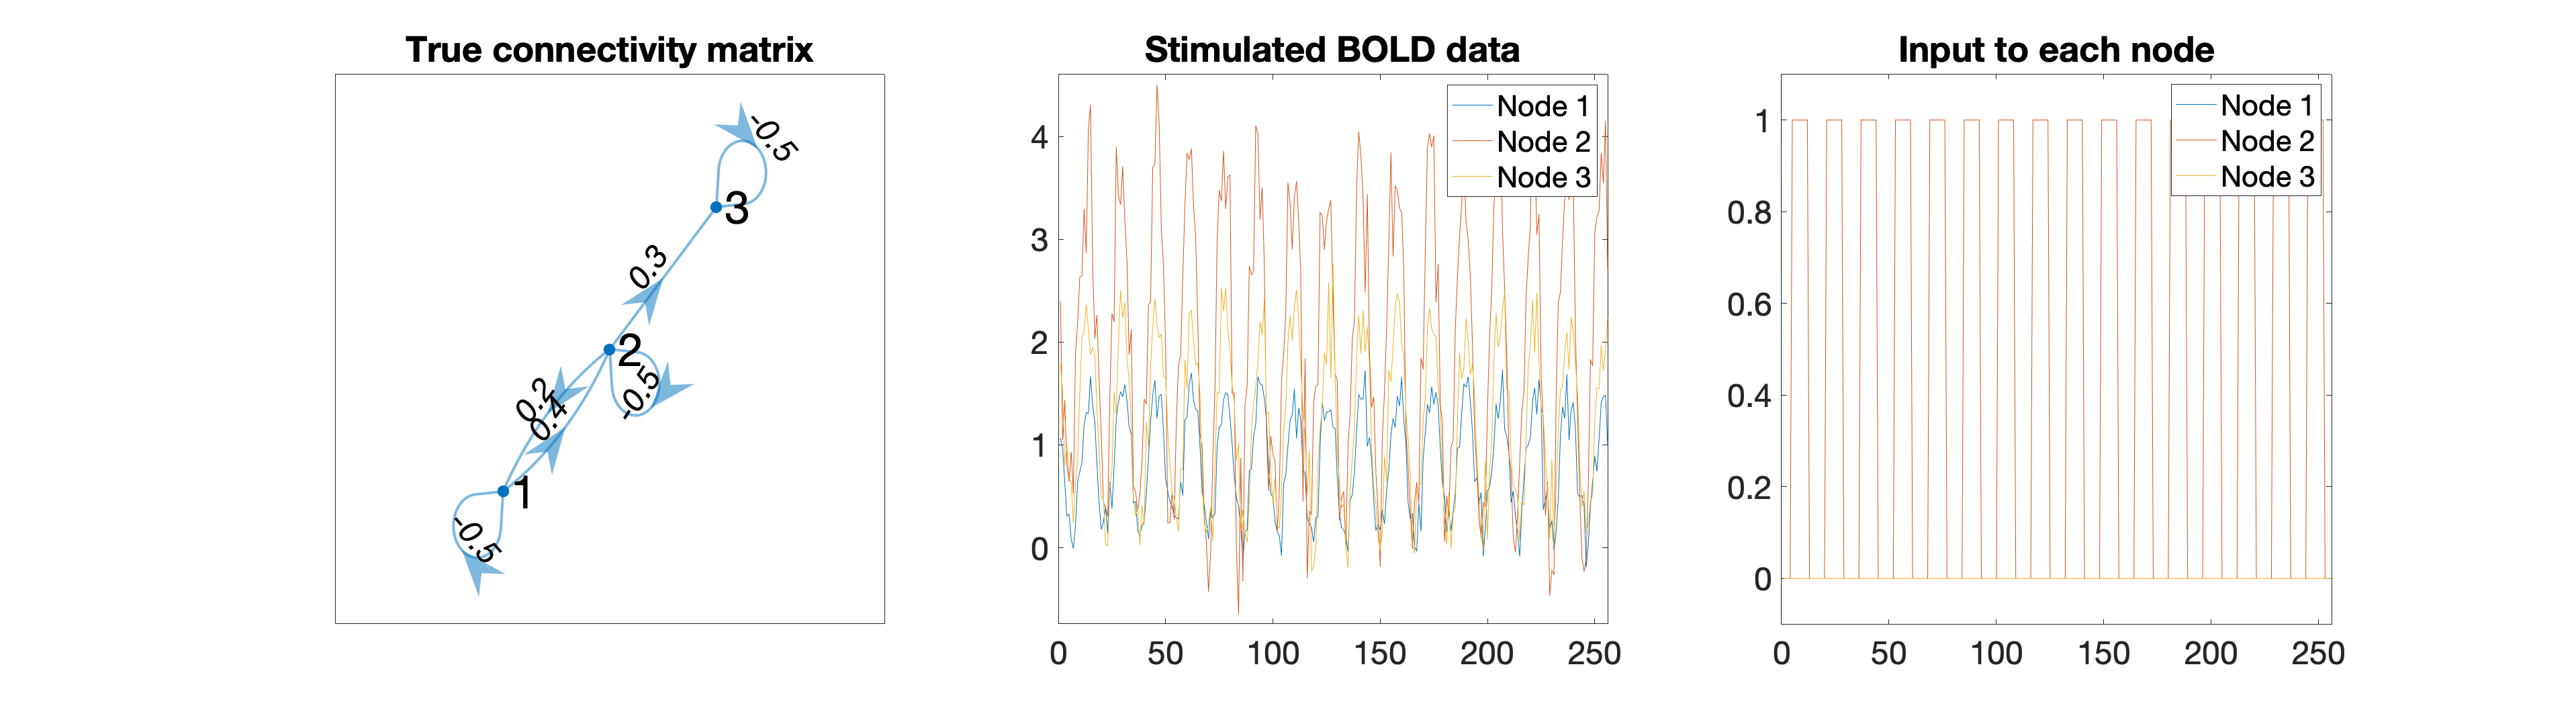

on_len = 16;
off_len = 8;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 2;
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

[DCM, options] = make_task_fmri(stim_options);

plot_sim_data(DCM)

[output, options] = tapas_rdcm_estimate(DCM, 's', options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


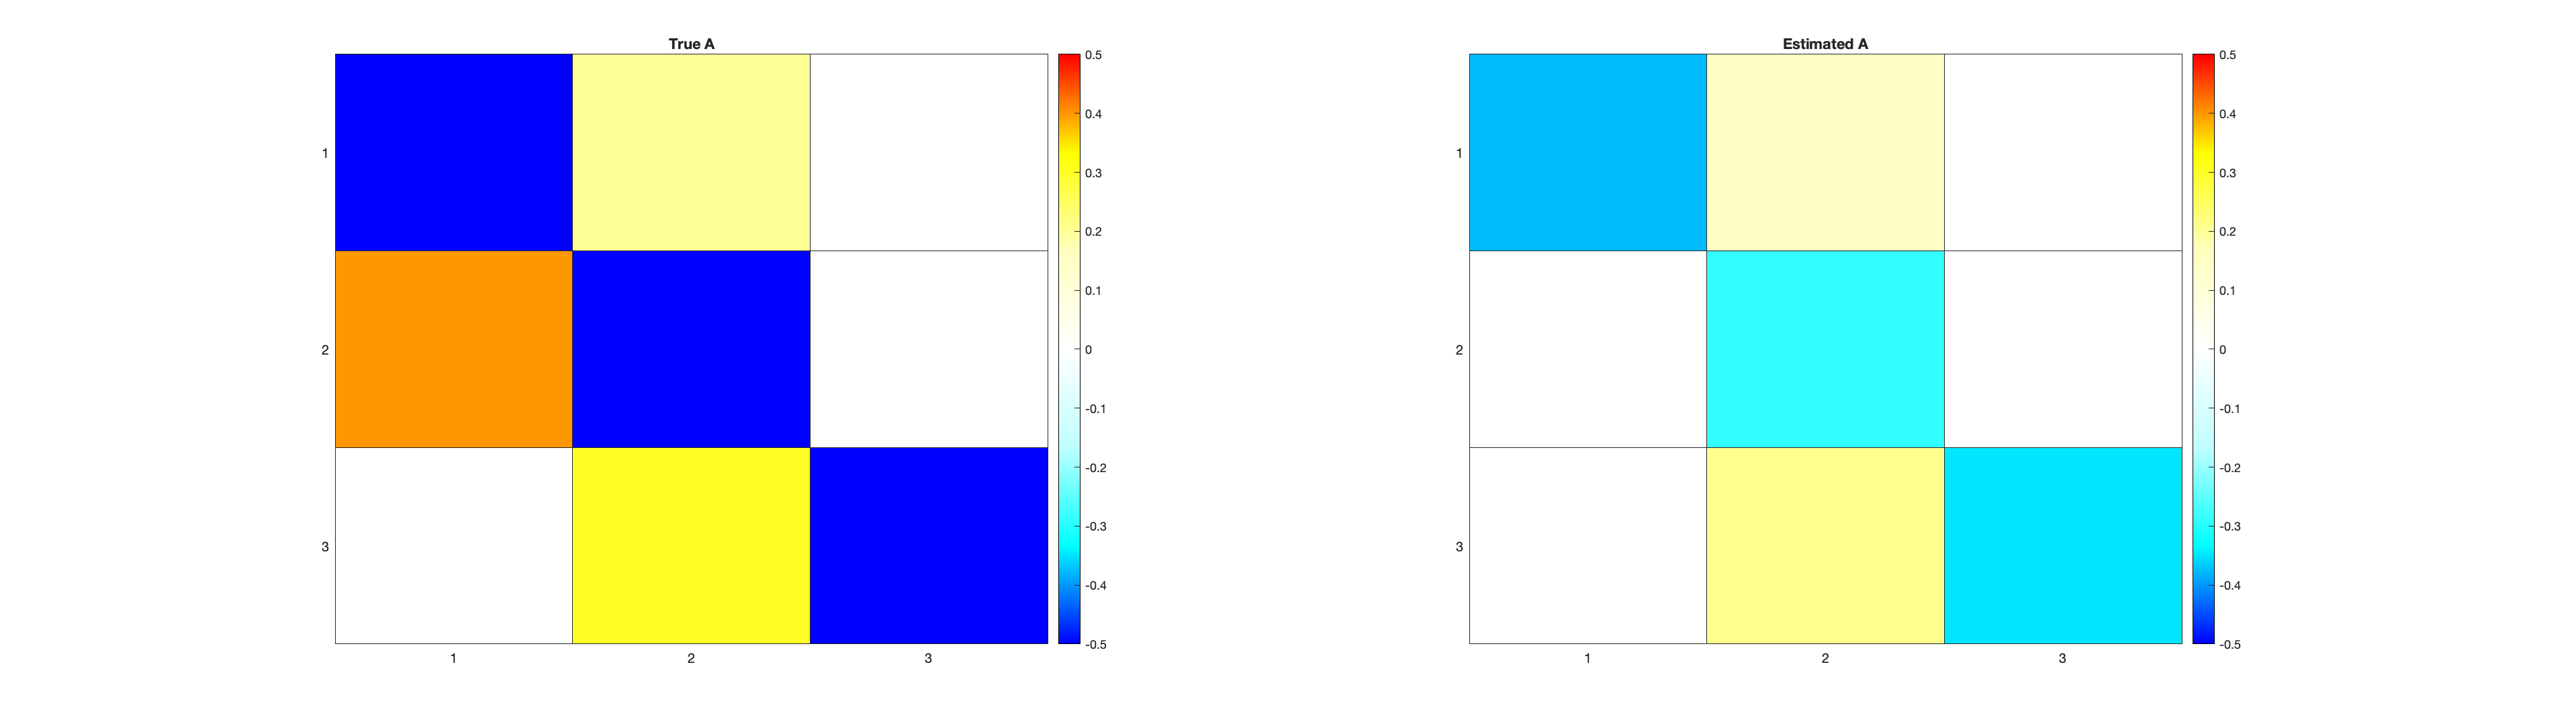

plot_true_est_connectivity(DCM, output)

## Long infrequent task to one node

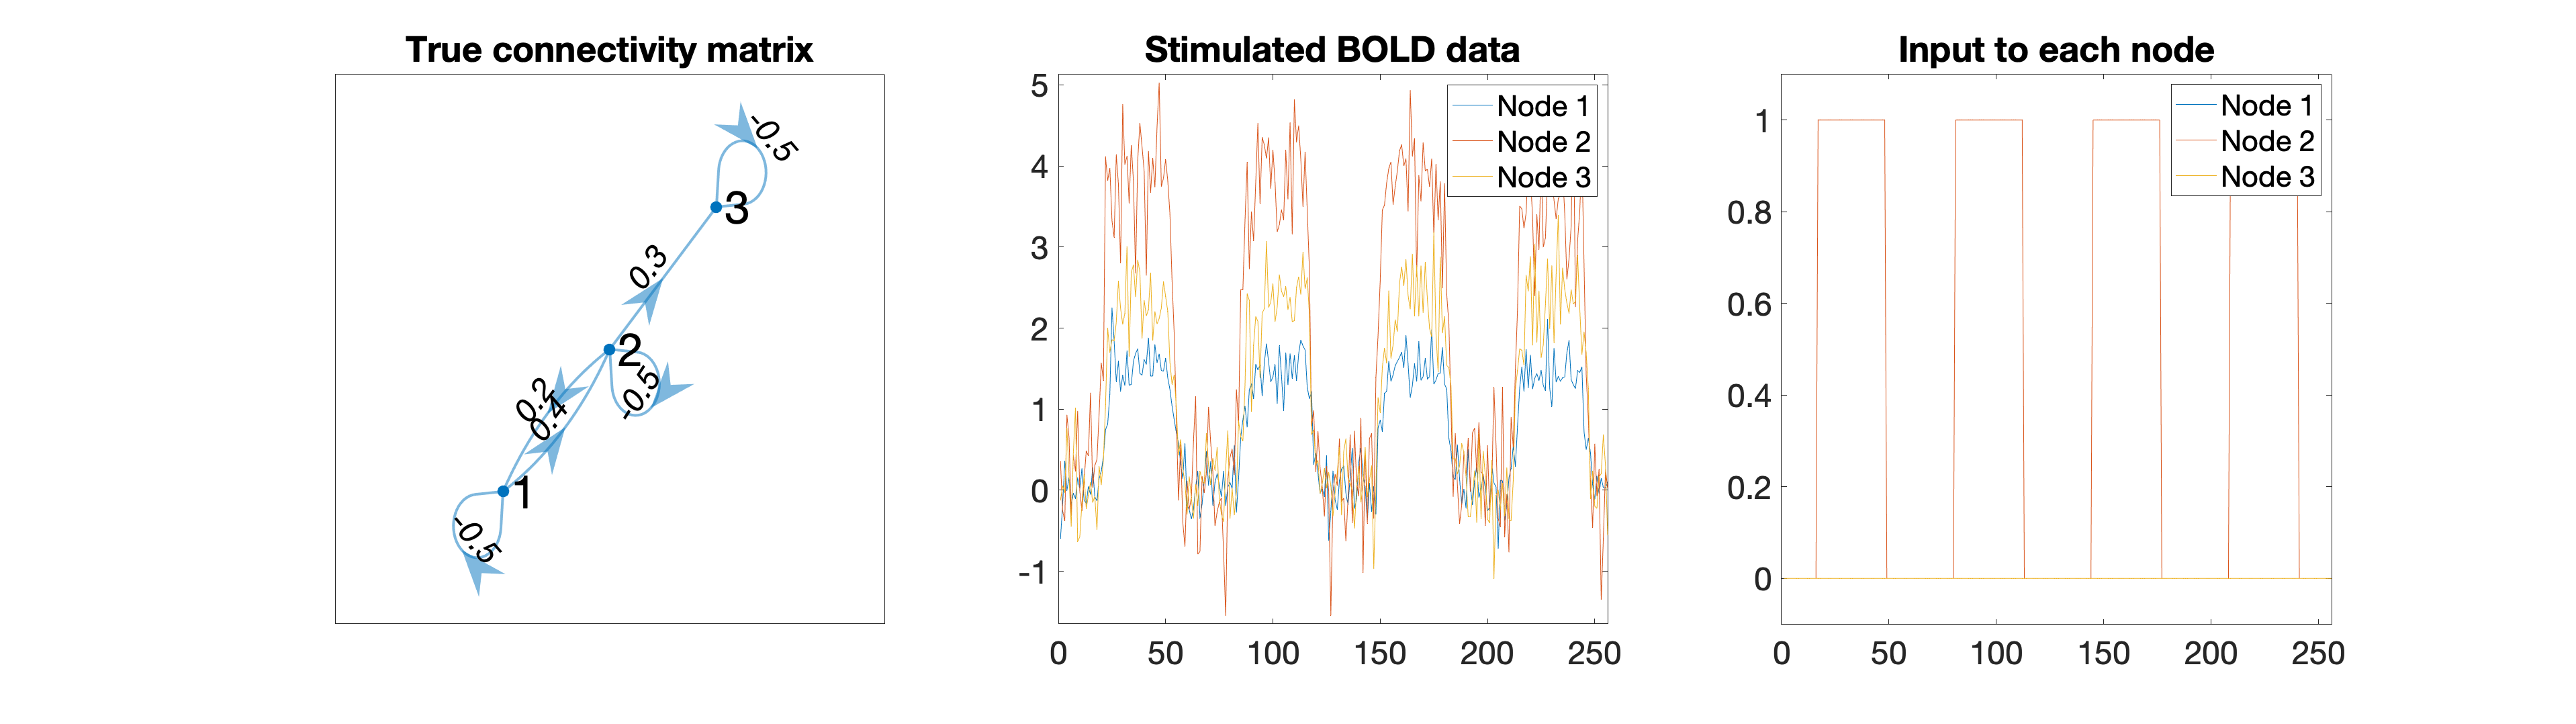

on_len = 64;
off_len = 32;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = 1/8;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 2;
stim_options.c = eye(stim_options.n);
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

[DCM, options] = make_task_fmri(stim_options);
plot_sim_data(DCM)

[output, options] = tapas_rdcm_estimate(DCM, 's', options, 2);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


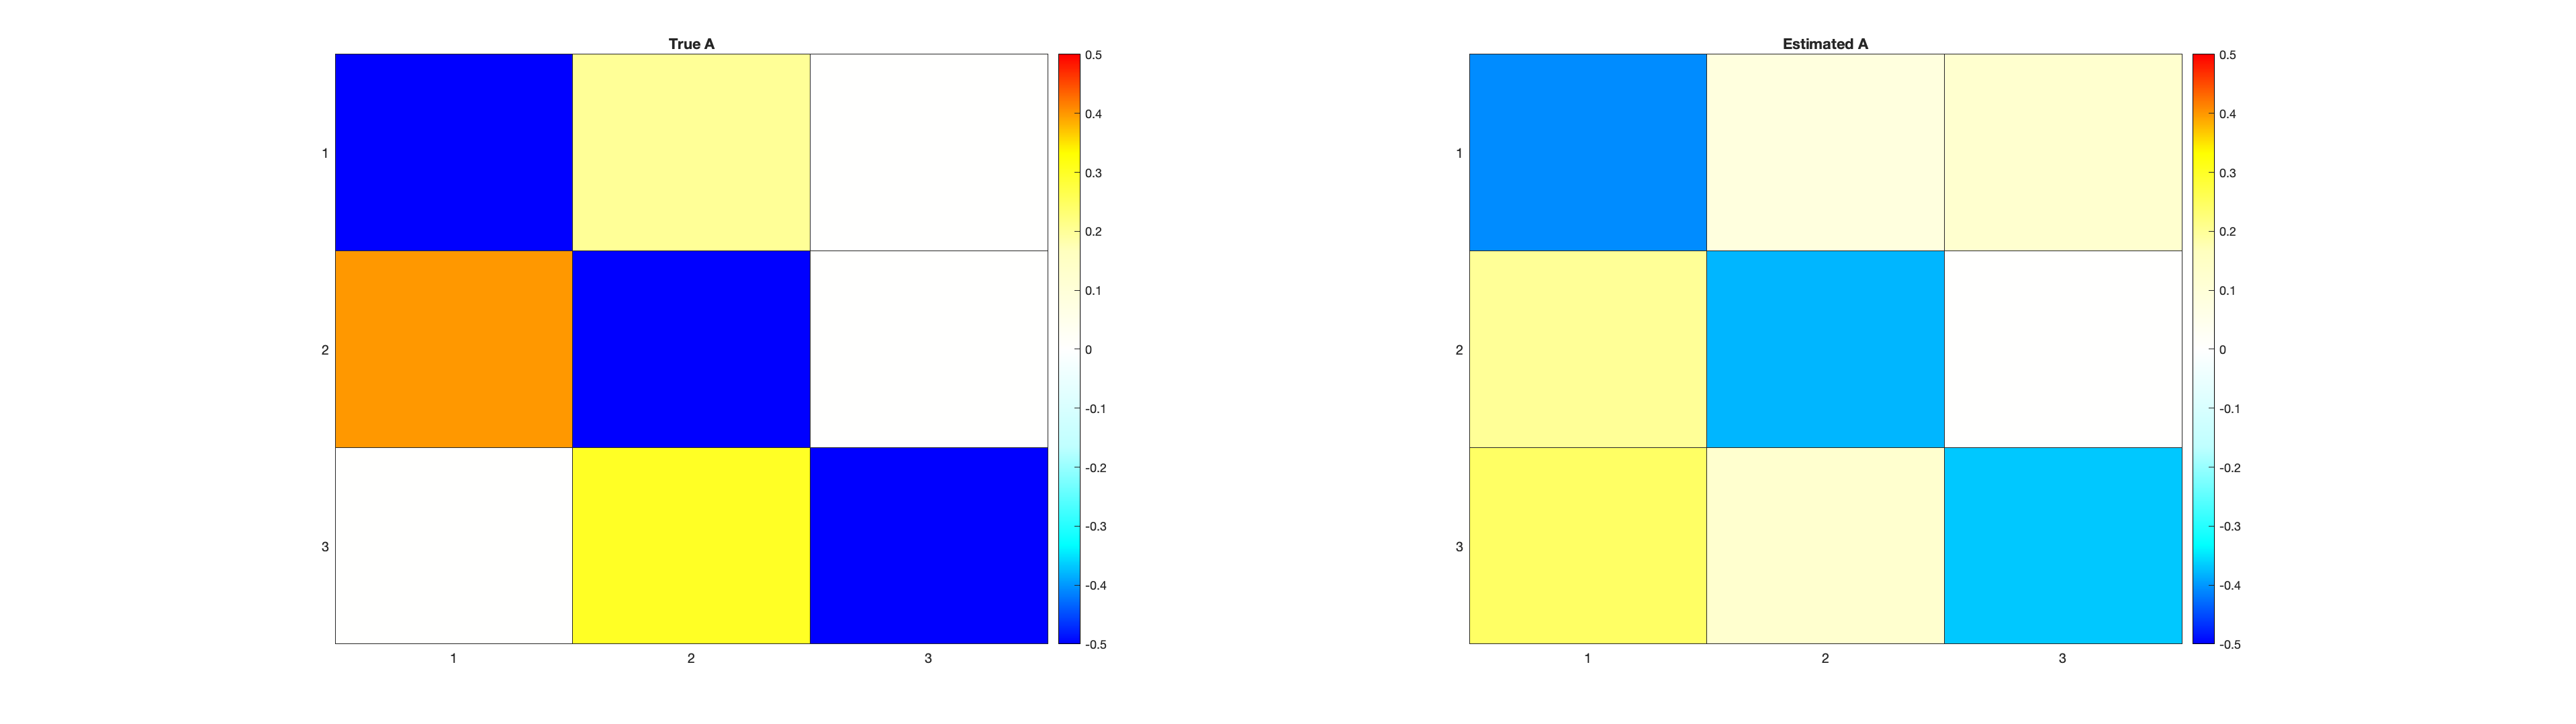

plot_true_est_connectivity(DCM, output)

## Average across multiple subjects

## Larger and sparser network